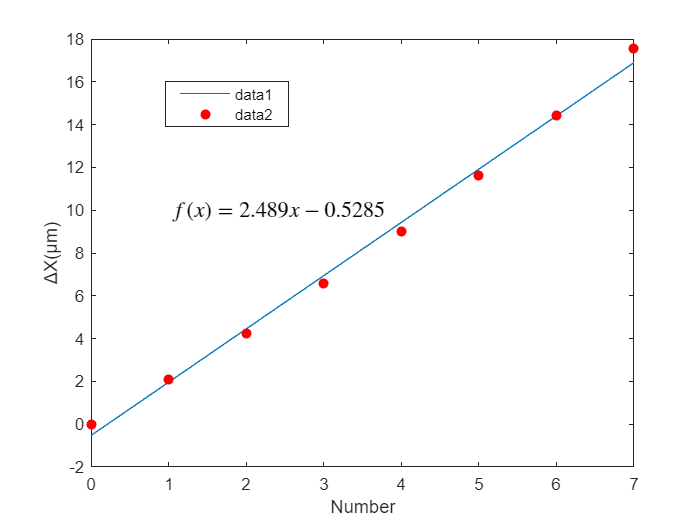

clear
M1 = readmatrix("寻峰2.xlsx");
ch = M1(:,4);
N = 6.02*10^22;
f = @(x)((2.5*x^0.625)*(45.7/(x/1000)*log(1+0.1/(x/1000) + 4.359*x/1000)))/...
((2.5*x^0.625) + (45.7/(x/1000)*log(1+0.1/(x/1000) + 4.359*x/1000)));
dd = N*f(ch(1))*1e-15;
deltaE = ch(1) - ch;
deltaX = deltaE/dd*1e7;
NN = 0:7;
ff = fit(NN',deltaX,'poly1');
hold on
plot(NN,ff(NN))
scatter(NN,deltaX,'red','filled')
legend("Position",[0.2356,0.75817,0.17679,0.086905])
box on
ylabel('ΔX(μm)')
xlabel('Number')
text(1,10,'$f(x) = 2.489x-0.5285$','Interpreter','latex','FontSize',13)